drawArrow = @(x,y,size) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0,'AutoScale','off','MaxHeadSize',size, 'LineWidth',1,"Color","black")   

drawArrow = function_handle with value:
    @(x,y,size)quiver(x(1),y(1),x(2)-x(1),y(2)-y(1),0,'AutoScale','off','MaxHeadSize',size,'LineWidth',1,"Color","black")


rho = 1.225

rho = 1.2250

v_up = 50

v_up = 50

v_down = -60

v_down = -60

Ctau_max_up = [0.177, 0.221, 0.2264, 0.307]

Ctau_max_up =     0.1770    0.2210    0.2264    0.3070


Ctau_max_down = [-0.236, -0.229, -0.223, -0.217]

Ctau_max_down =    -0.2360   -0.2290   -0.2230   -0.2170


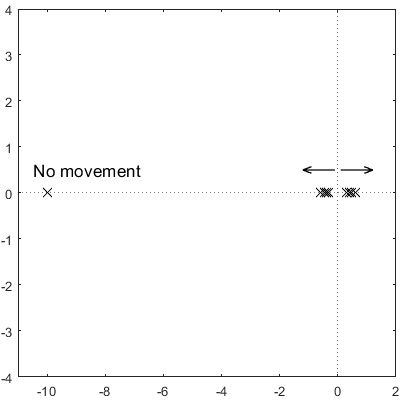


% Ascent
figure
for i = 1:4
    A = [-1/t_V,  0, 0;
          cm(i)/I_yz_lookup(i*10-9), 0, (0.5*rho*A_rocket*v_up^2*Ctau_max_up(i)/10)/I_yz_lookup(i*10-9);
          0, 1, 0];
    
    b = [1/t_V; 0; 0];
    c = [0,0,1];
    d = 0;
    sysC = ss(A,b,c,d);
%     pzplot(sysC);
    black_pz(sysC,-11,2,-4,4)
    hold on
end
drawArrow([0.1,1.2],[0.5,0.5],0.8)
drawArrow([-0.1,-1.2],[0.5,0.5],0.8)
text(-10.5,0.5,"No movement","FontSize",13)

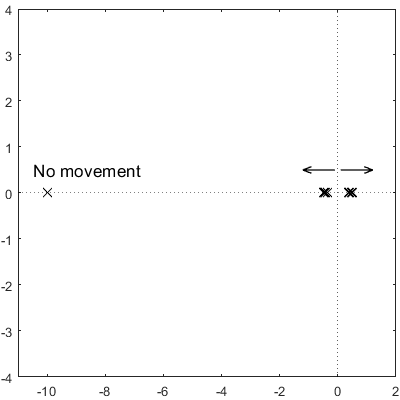


% Descent
figure
for i = 1:4
    A = [-1/t_V,  0, 0;
          cm(i)/I_yz_lookup(i*10-9), 0, -(0.5*rho*A_rocket*v_up^2*Ctau_max_down(i)/10)/I_yz_lookup(i*10-9);
          0, 1, 0];
    
    b = [1/t_V; 0; 0];
    c = [0,0,1];
    d = 0;
    
    sysC = ss(A,b,c,d);
%     pzplot(sysC);
    black_pz(sysC,-11,2,-4,4)
    hold on
end
drawArrow([0.1,1.2],[0.5,0.5],0.8)
drawArrow([-0.1,-1.2],[0.5,0.5],0.8)
text(-10.5,0.5,"No movement","FontSize",13)

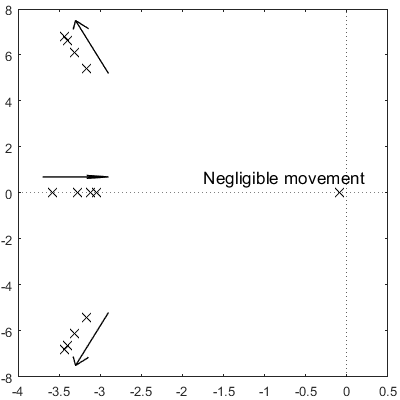


% Ascent With control

figure
for i = 1:4
    A = [-1/t_V,  0, 0;
          cm(i)/I_yz_lookup(i*10-9), 0, (0.5*rho*A_rocket*v_up^2*Ctau_max_up(i)/10)/I_yz_lookup(i*10-9);
          0, 1, 0];
    
    b = [1/t_V; 0; 0];
    c = [0,0,1];
    d = 0;
    % Rate controller
    c_rate=[0,1,0];
    A_rate = [A-b*C_rate.Kp*c_rate, b*C_rate.Ki;
              -c_rate              , 0];
    b_rate = [b*C_rate.Kp;1];
    
    % Angle controller
    c_ang = [0,0,1,0];
    A_ang = A_rate - b_rate*C_ang.Kp*c_ang;
    b_ang = b_rate*(C_ang.Kp/T_max);
    sysC_ang = ss(A_ang,b_ang,c_ang,d);
%     pzplot(sysC_ang)
    black_pz(sysC_ang,-4,0.5,-8,8)
    hold on
end
drawArrow([-3.7,-2.9],[0.7,0.7],1)
drawArrow([-2.9,-3.3],[5.2,7.5],0.5)
drawArrow([-2.9,-3.3],[-5.2,-7.5],0.5)
text(-1.75,0.7,"Negligible movement","FontSize",	13)

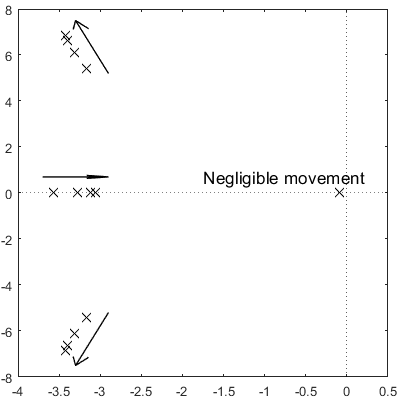


% Descent With control
figure
for i = 1:4
        A = [-1/t_V,  0, 0;
          cm(i)/I_yz_lookup(i*10-9), 0, -(0.5*rho*A_rocket*v_up^2*Ctau_max_down(i)/10)/I_yz_lookup(i*10-9);
          0, 1, 0];
    
    b = [1/t_V; 0; 0];
    c = [0,0,1];
    d = 0;

    % Rate controller
    c_rate=[0,1,0];
    A_rate = [A-b*C_rate.Kp*c_rate, b*C_rate.Ki;
              -c_rate              , 0];
    b_rate = [b*C_rate.Kp;1];
    
    % Angle controller
    c_ang = [0,0,1,0];
    A_ang = A_rate - b_rate*C_ang.Kp*c_ang;
    b_ang = b_rate*(C_ang.Kp/T_max);
    sysC_ang = ss(A_ang,b_ang,c_ang,d);
%     pzplot(sysC_ang)
    black_pz(sysC_ang,-4,0.5,-8,8)
    hold on
end
drawArrow([-3.7,-2.9],[0.7,0.7],1)
drawArrow([-2.9,-3.3],[5.2,7.5],0.5)
drawArrow([-2.9,-3.3],[-5.2,-7.5],0.5)
text(-1.75,0.7,"Negligible movement","FontSize",	13)